clear; close all
% Load the model and apply the corrections for *all* models
cd('../modelCuration/')
v9_1_0;

Identifier of new metabolite "sulphate[m]": s_4333
Identifier of new reaction "oxaloacetate/sulphate antiport, mitochondrial": r_4783
Identifier of new reaction "malate/sulphate antiport, mitochondrial": r_4784
Current biomass adds up to 0.9949 g/g. Protein fraction is scaled from 0.4597 to 0.4648 g/g to reach 1 g/g total biomass.
P -> 0.46483 g/gDW
C -> 0.38311 g/gDW
R -> 0.054138 g/gDW
D -> 0.0032743 g/gDW
L -> 0.087299 g/gDW
I -> 0.002504 g/gDW
F -> 0.0048504 g/gDW
X -> 1 gDW/gDW
Growth = 0.083423 1/h
 


modelAn = anaerobicModel(model);
sol = solveLP(modelAn) % No solution

sol = struct with fields:
         x: [4126×1 double]
         f: 0
      stat: 1
       msg: 'Optimal solution found'
    sPrice: [2802×1 double]
     rCost: [4126×1 double]


#### Conclusion:

No solution (sol.f = 0) when the model goes through the anaerobicModel script.

## Make 3 alternative models

### Alternative 1: allow glycine secretion

model_GlySecr   = setParam(model,'lb',{'r_1173'},-1000);
modelAn_GlySecr = anaerobicModel(model_GlySecr);
sol = solveLP(modelAn_GlySecr)

sol = struct with fields:
         x: [4126×1 double]
         f: 0.0110
      stat: 1
       msg: 'Optimal solution found'
    sPrice: [2802×1 double]
     rCost: [4126×1 double]


printFluxes(modelAn_GlySecr,sol.x)

EXCHANGE FLUXES:
r_1548	((R)-pantothenate exchange):	-2.0808e-06
r_1654	(ammonium exchange):	-0.070712
r_1672	(carbon dioxide exchange):	1.7906
r_1714	(D-glucose exchange):	-1
r_1757	(ergosterol exchange):	-0.00040886
r_1761	(ethanol exchange):	1.704
r_1808	(glycerol exchange):	0.12601
r_1810	(L-glycine exchange):	3.6208e-05
r_1814	(glycolaldehyde exchange):	7.0747e-07
r_1832	(H+ exchange):	0.064692
r_1861	(iron(2+) exchange):	-3.3293e-07
r_1967	(nicotinate exchange):	-6.6476e-05
r_1994	(palmitoleate exchange):	-0.0010215
r_2005	(phosphate exchange):	-0.0030556
r_2020	(potassium exchange):	-3.9754e-05
r_2049	(sodium exchange):	-4.3478e-05
r_2056	(succinate exchange):	0.0020509
r_2060	(sulphate exchange):	-0.00094993
r_2100	(water exchange):	0.12025
r_2111	(growth):	0.010952
r_2189	(oleate exchange):	-0.00033757
r_4593	(chloride exchange):	-1.4128e-05
r_4594	(Cu2(+) exchange):	-7.2171e-06
r_4595	(Mn(2+) exchange):	-2.9898e-05
r_4596	(Zn(2+) exchange):	-8.1918e-06
r_4597	(Mg(2+) exchange

Notice the flux through r_1810: glycine secretion.

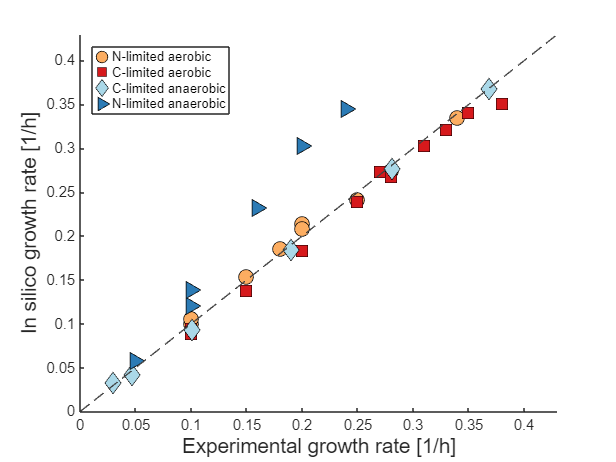

R2_GlySecr = single
0.9078

R2_GlySecr = growth(model_GlySecr)

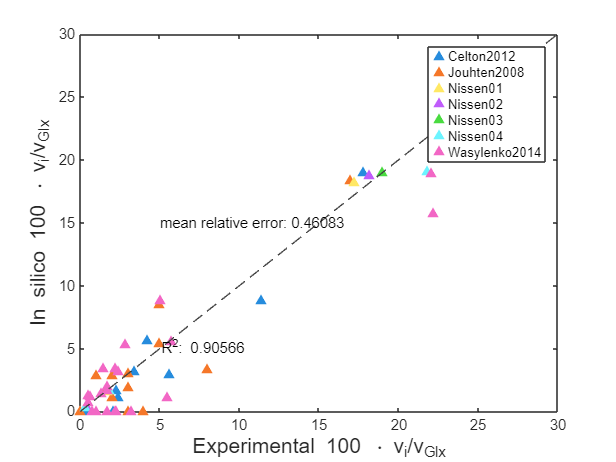

R2anFlux_GlySecr = 0.9057

R2anFlux_GlySecr = anaerobic_flux_predictions(modelAn_GlySecr)

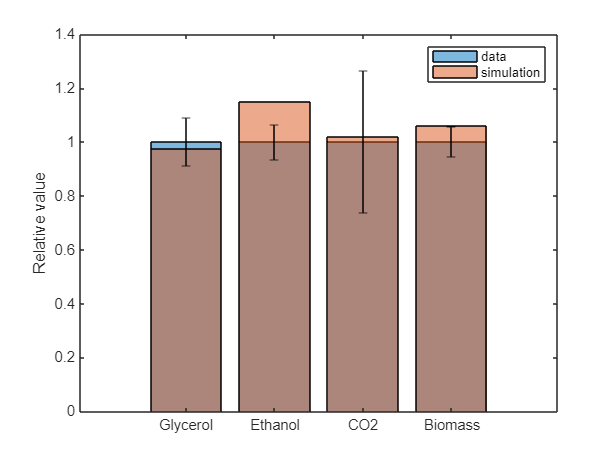

plotAnaerobic(modelAn_GlySecr)

#### Conclusion:

Good results overall (R2 = 0.9078 and 0.9057, good glycerol production), but the observed glycine secretion has never been reported (as far as I know).

### Alternative 2: enable glycine cleavage system

model_GCVon = setParam(model,'ub',{'r_0501','r_0507','r_0509'},1000);
modelAn_GCVon = anaerobicModel(model_GCVon);
sol = solveLP(modelAn_GCVon)

sol = struct with fields:
         x: [4126×1 double]
         f: 0.0110
      stat: 1
       msg: 'Optimal solution found'
    sPrice: [2802×1 double]
     rCost: [4126×1 double]


printFluxes(modelAn_GCVon,sol.x)

EXCHANGE FLUXES:
r_1548	((R)-pantothenate exchange):	-2.0941e-06
r_1654	(ammonium exchange):	-0.071129
r_1672	(carbon dioxide exchange):	1.8058
r_1714	(D-glucose exchange):	-1
r_1757	(ergosterol exchange):	-0.00041148
r_1761	(ethanol exchange):	1.7311
r_1808	(glycerol exchange):	0.10202
r_1814	(glycolaldehyde exchange):	7.1201e-07
r_1832	(H+ exchange):	0.06507
r_1861	(iron(2+) exchange):	-3.3506e-07
r_1967	(nicotinate exchange):	-6.6902e-05
r_1994	(palmitoleate exchange):	-0.001028
r_2005	(phosphate exchange):	-0.0030752
r_2020	(potassium exchange):	-4.0009e-05
r_2049	(sodium exchange):	-4.3756e-05
r_2056	(succinate exchange):	0.002064
r_2060	(sulphate exchange):	-0.00095602
r_2100	(water exchange):	0.13341
r_2111	(growth):	0.011022
r_2189	(oleate exchange):	-0.00033973
r_4593	(chloride exchange):	-1.4218e-05
r_4594	(Cu2(+) exchange):	-7.2634e-06
r_4595	(Mn(2+) exchange):	-3.0089e-05
r_4596	(Zn(2+) exchange):	-8.2443e-06
r_4597	(Mg(2+) exchange):	-1.3695e-05
r_4600	(Ca(2+) exchange):	-

Notice the absence of r_1810: no glycine secretion.

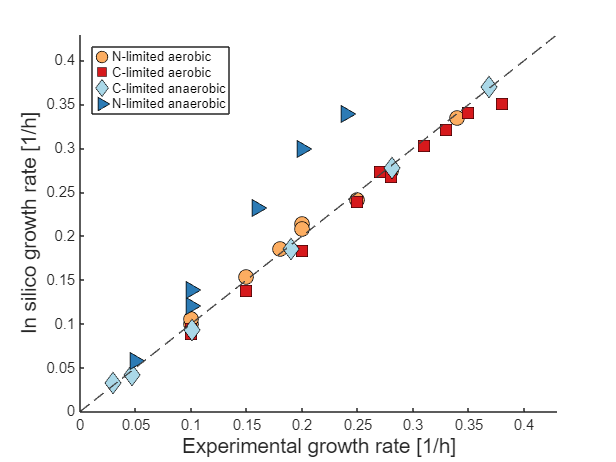

R2_GCVon = single
0.9129

R2_GCVon = growth(model_GCVon)

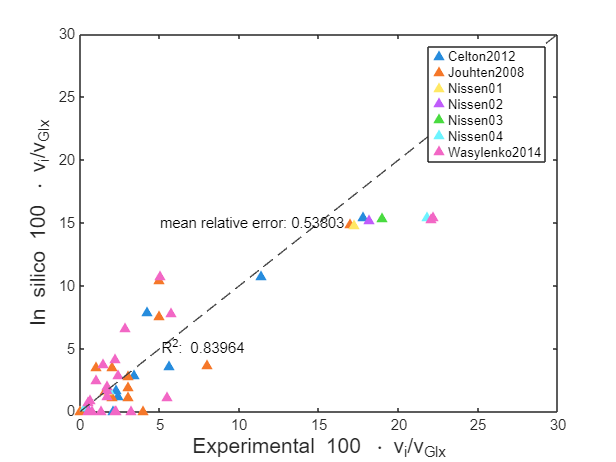

R2anFlux_GCVon = 0.8396

R2anFlux_GCVon = anaerobic_flux_predictions(modelAn_GCVon)

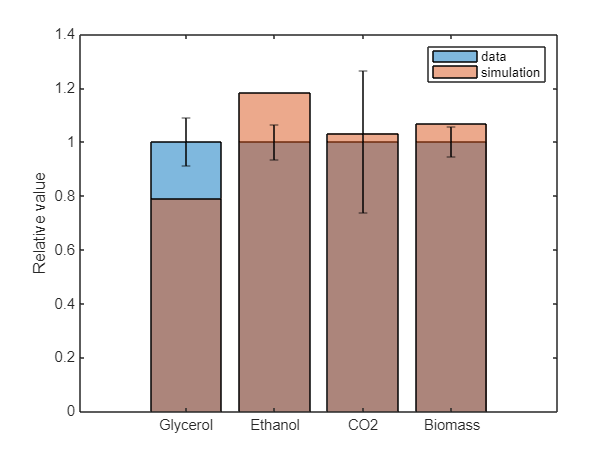

plotAnaerobic(modelAn_GCVon)

#### Conclusion

Good general growth prediction (R2 = 0.9129) , but worst prediction of anaerobic fluxes (R2 = 0.8396). Too low glycerol secretion (80%).

### Alternative 3: reduce methionine in biomass

Here we need reduce the methionine content in the protein fraction of the biomass formulation by the same amount as glycine was secreted in alternative 1. Less methionine required = less glycine secreted. We need to run a few more lines to find out by how much to reduce methionine content.

% Determine how much glycine is secreted per biomass
sol = solveLP(modelAn_GlySecr);
glySecretion    = sol.x(getIndexes(modelAn_GlySecr,'r_1173','rxns'));
% Determine how methionine flux into biomass
tRNAmetIdx      = getIndexes(model,{'Met-tRNA(Met)[c]','tRNA(Met)[c]'},'metcomps');
oldMetProtCoeff = full(modelAn_GlySecr.S(tRNAmetIdx(1),3411));
metToProtein    = oldMetProtCoeff * sol.f;
% Balance the methionine flux with the secreted glycine
balancedMetFlux = metToProtein - glySecretion;
% Set new Met-tRNA coefficient in protein pseudoreaction
newMetProtCoeff = ((balancedMetFlux) / sol.f) * 0.9;
fprintf('Methionine in protein content decreased from %.5f to %.5f.\n',-oldMetProtCoeff,-newMetProtCoeff)

Methionine in protein content decreased from 0.05888 to 0.05002.


% Base model on the glycine-secretion model, so that we can confirm that NO
% glycine will be secreted.
model_lessMet   = model_GlySecr;
model_lessMet.S(tRNAmetIdx,3411) = [newMetProtCoeff, -newMetProtCoeff];
% Scale protein content to compensate for increased methionine
[X,P]  = sumBioMass(model_lessMet,false);
model_lessMet = scaleBioMass(model_lessMet,'protein',(1-X)+P);

P -> 0.46483 g/gDW
C -> 0.38311 g/gDW
R -> 0.054138 g/gDW
D -> 0.0032743 g/gDW
L -> 0.087299 g/gDW
I -> 0.002504 g/gDW
F -> 0.0048504 g/gDW
X -> 1 gDW/gDW
Growth = 0.081672 1/h
 


modelAn_lessMet = anaerobicModel(model_lessMet);
sol = solveLP(modelAn_lessMet)

sol = struct with fields:
         x: [4126×1 double]
         f: 0.0110
      stat: 1
       msg: 'Optimal solution found'
    sPrice: [2802×1 double]
     rCost: [4126×1 double]


printFluxes(modelAn_lessMet,sol.x)

EXCHANGE FLUXES:
r_1548	((R)-pantothenate exchange):	-2.0808e-06
r_1654	(ammonium exchange):	-0.070731
r_1672	(carbon dioxide exchange):	1.7905
r_1714	(D-glucose exchange):	-1
r_1757	(ergosterol exchange):	-0.00040885
r_1761	(ethanol exchange):	1.7041
r_1808	(glycerol exchange):	0.12603
r_1814	(glycolaldehyde exchange):	7.0746e-07
r_1832	(H+ exchange):	0.064999
r_1861	(iron(2+) exchange):	-3.3292e-07
r_1967	(nicotinate exchange):	-6.6475e-05
r_1994	(palmitoleate exchange):	-0.0010215
r_2005	(phosphate exchange):	-0.0030555
r_2020	(potassium exchange):	-3.9753e-05
r_2049	(sodium exchange):	-4.3477e-05
r_2056	(succinate exchange):	0.0020508
r_2060	(sulphate exchange):	-0.00085443
r_2100	(water exchange):	0.12007
r_2111	(growth):	0.010951
r_2189	(oleate exchange):	-0.00033756
r_4593	(chloride exchange):	-1.4127e-05
r_4594	(Cu2(+) exchange):	-7.217e-06
r_4595	(Mn(2+) exchange):	-2.9897e-05
r_4596	(Zn(2+) exchange):	-8.1916e-06
r_4597	(Mg(2+) exchange):	-1.3608e-05
r_4600	(Ca(2+) exchange):

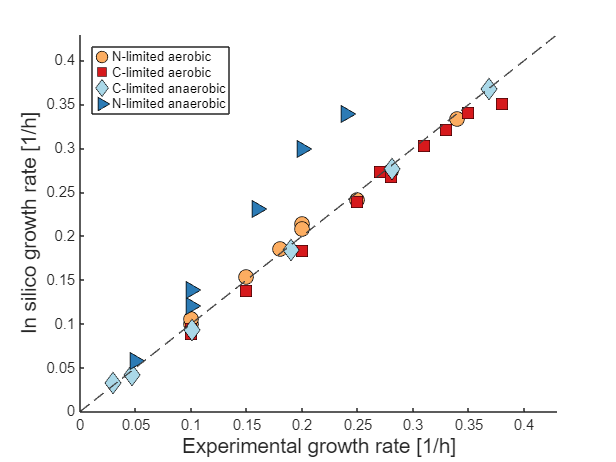

R2_lessMet = single
0.9125

% No glycine secretion required, switch-off
model_lessMet    = setParam(model_lessMet,'lb',{'r_1173'},0);
R2_lessMet = growth(model_lessMet)

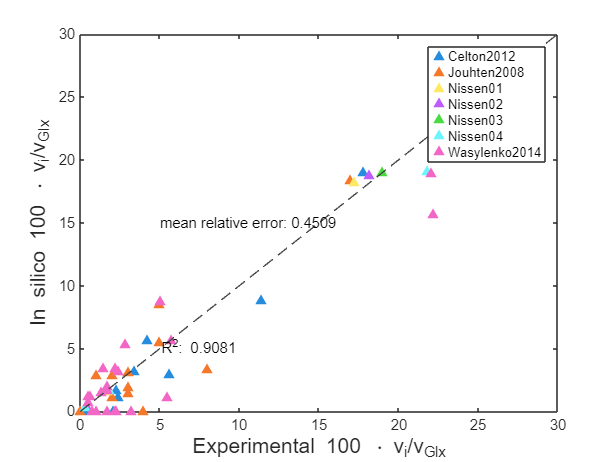

R2anFlux_lessMet = 0.9081

R2anFlux_lessMet = anaerobic_flux_predictions(modelAn_lessMet)

plotAnaerobic(modelAn_lessMet)

#### Conclusion

Good results overall (R2 = 0.9125 and 0.9058, good glycerol production).

## Compare with previous model versions

We will take the model with less methionine as the new model version, compare it with performance of 9.0.2, as well as compare the old and new anaerobicModel

model902 = loadYeastModel;
model    = model_lessMet;

### Run growth tests

Use the 9.1.0 model with the new anaerobic script, this should be the best model.

R2 in 9.1.0 model with new anaerobic script: 0.9125


R2new = growth(model); fprintf("R2 in 9.1.0 model with new anaerobic script: %.4f\n", R2new)

Use the 9.1.0 model, but use the old `anaerobicModel` script. [Note that this is not *exactly* the old `anaerobicModel` script, it has been curated to prevent the curation of protein-content in nitrogen limiting conditions to be overwritten in anaerobic conditions].

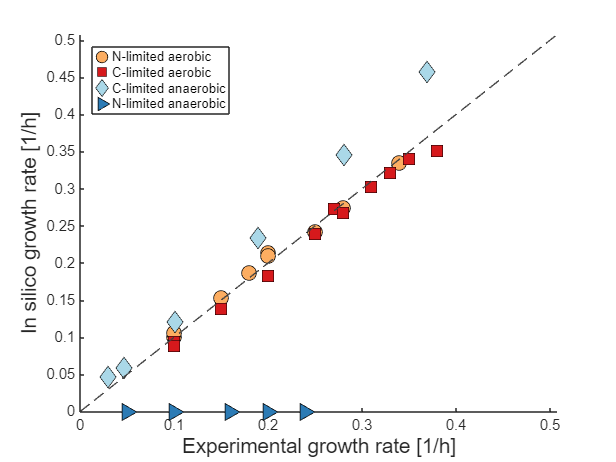

R2 in 9.1.0 model with old anaerobic script: 0.7185


R2old = growthOld(model); fprintf("R2 in 9.1.0 model with old anaerobic script: %.4f\n", R2old)

Model fails in N-limited anaerobic conditions. Again linked to glycine secretion, let's enable glycine secretion to show this:

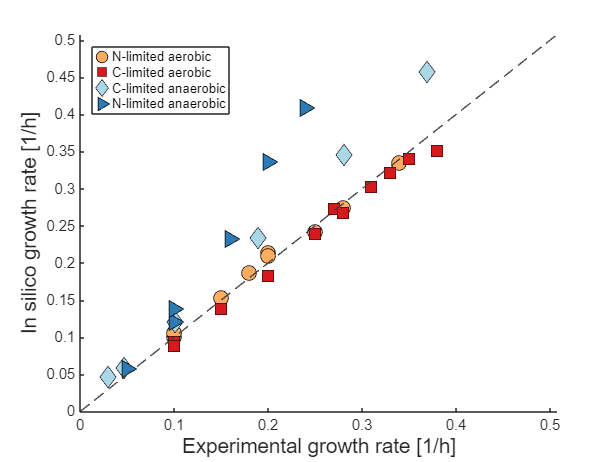

R2 in 9.1.0 model (wiht glycine secretion) with old anaerobic script: 0.8388


tmp    = setParam(model_lessMet,'lb',{'r_1173'},-1000);
R2old_GlySecr = growthOld(tmp); fprintf("R2 in 9.1.0 model (wiht glycine secretion) with old anaerobic script: %.4f\n", R2old_GlySecr)

Did the generic curation have much influence? Repeat the two curves (with new and old `anaerobicModel` script) with the 9.0.2 model.

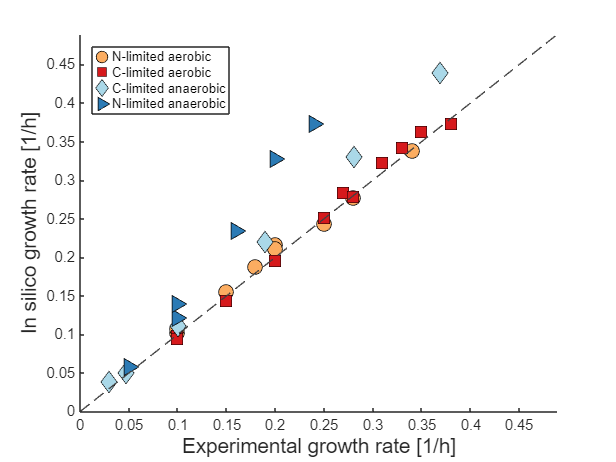

R2 in 9.1.0 model with new anaerobic script: 0.8985


R2new902 = growth(model902); fprintf("R2 in 9.1.0 model with new anaerobic script: %.4f\n", R2new902)

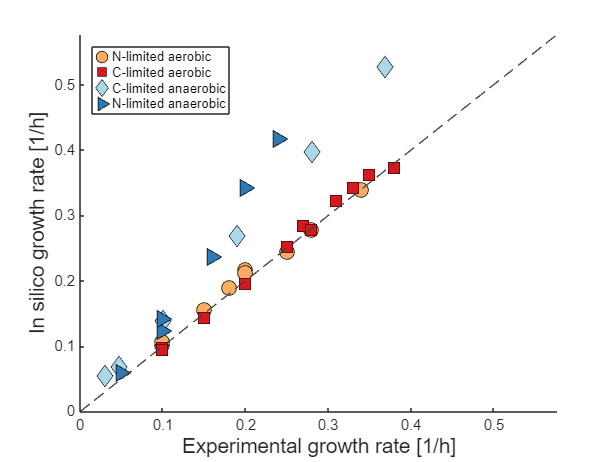

R2 in 9.1.0 model with old anaerobic script: 0.8256


R2old902 = growthOld(model902); fprintf("R2 in 9.1.0 model with old anaerobic script: %.4f\n", R2old902)

### Conclusions from growth curve:

R2 increased from 0.839 to 0.9125 as a consequence of the new `anaerobicModel` script (and disabled the undesired glycine secretion).

The generic curations in 9.1.0 also had a beneficial effect, as repeating the same simulations with the 9.0.2 version of the model gave R2 of 0.8256 and 0.8985 for old and new `anaerobicModel` scripts.

**The 9.1.0 model with new anaerobicModel script is superior to predict growth rate. Both 9.0.2 => 9.1.0 and new anaerobicModel script by themselves have beneficial effects.**

## Convert to anaerobic

Convert all models to anaerobic for second set of model testing.

cd('../otherChanges/')
modelAn = anaerobicModel(model);
modelAnOld = anaerobicModelOld(model);
modelAn902 = anaerobicModel(model902);
modelAnOld902 = anaerobicModelOld(model902);
cd('../modelTests/');

## Run flux prediction tests

In the same order as before, look at the 9.1.0 with new and old `anaerobicModel`, followed by 9.0.2.

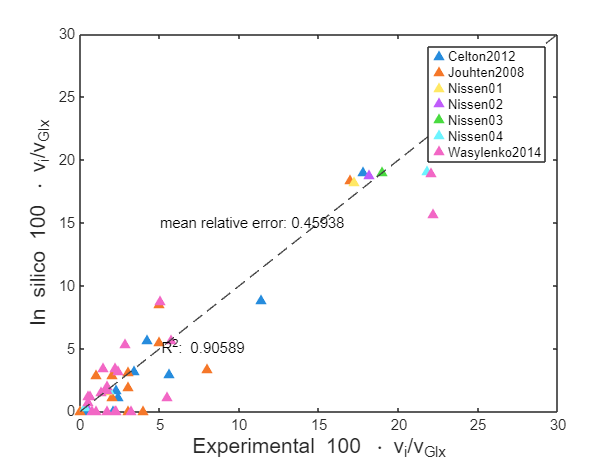

R2fluxnew = anaerobic_flux_predictions(modelAn);

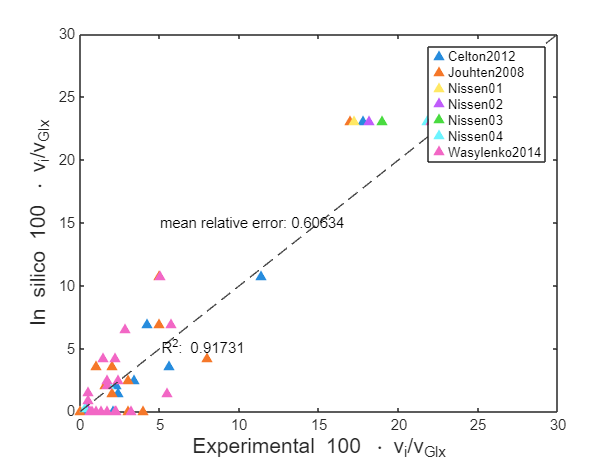

R2fluxold = anaerobic_flux_predictions(modelAnOld);

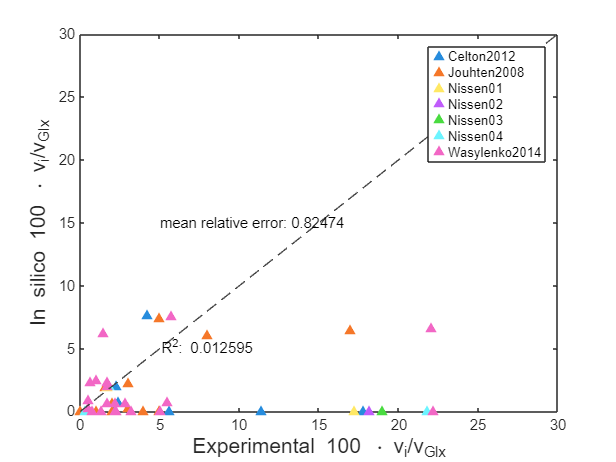

R2fluxnew902 = anaerobic_flux_predictions(modelAn902);

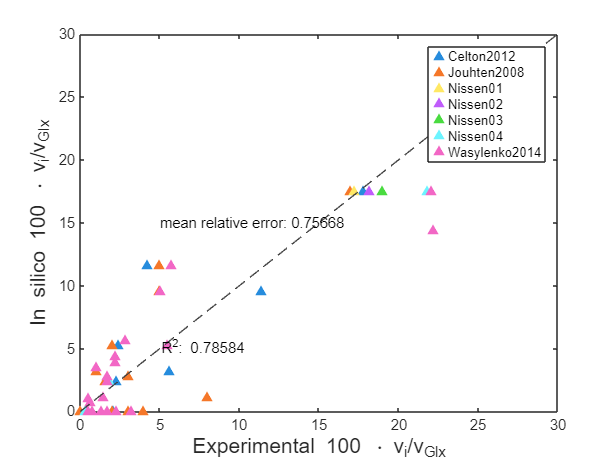

R2fluxold902 = anaerobic_flux_predictions(modelAnOld902);

### Conclusions

R2 **decreased** from 0.91718 to 0.90849 as a consequence of the new anaerobicModel script.

The generic curations in 9.1.0 had a major effect, as repeating the same simulations with the 9.0.2 version of the model gave R2 of 0.012595 and 0.78584 for old and new anaerobicModel scripts.

**The combination of ****9.1.0 model and new anaerobicModel script**** is superior to the combination of ****9.0.2. and the old anaerobicModel script****. When investigated ****separately****, the benefit of 9.1.0 and new anaerobicModel ****by themselves is more complicated****.**

## Plot exchange fluxes from Gustav's paper

plotAnaerobic(modelAn)

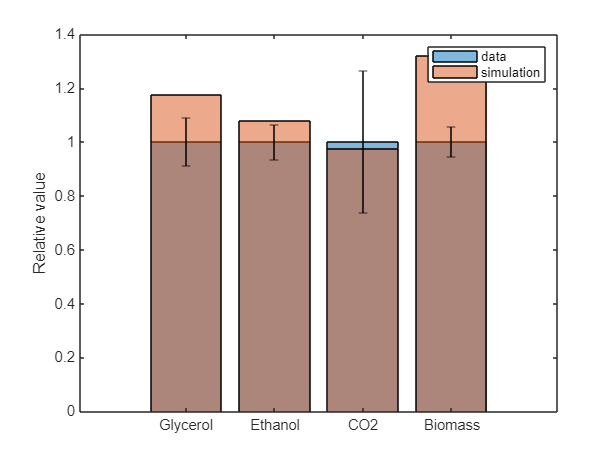

plotAnaerobic(modelAnOld)

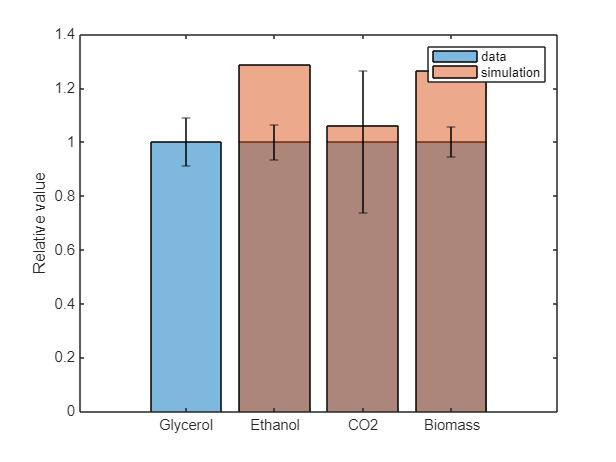

plotAnaerobic(modelAn902)

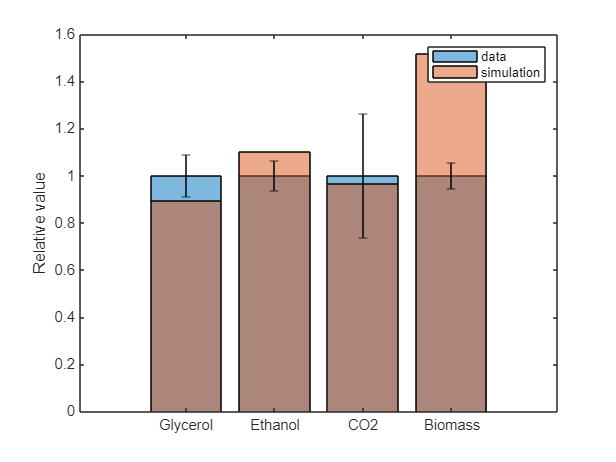

plotAnaerobic(modelAnOld902)

### **Conclusions**

The **combination of 9.1.0 and new anaerobicModel script is superior** (visual comparison, should we quantify it?).

**When investigated separately, the benefit of 9.1.0 and new anaerobicModel by themselves is more complicated.**

## Check ratio between ATPase and ammonium transport

This value is expected to be around 1.

modelAn = setParam(modelAn,'eq','r_1714',-23);
res=solveLP(modelAn,1);
FLUX = res.x;
v_AStr = res.x(getIndexes(modelAn,'r_1115','rxns'));
v_ATPase = res.x(getIndexes(modelAn,'r_0227','rxns'));
v_glc = res.x(getIndexes(modelAn,'r_1714','rxns'));
fprintf("Ratio of ATPase vs. ammonium transport: %.2f.\n", v_ATPase / v_AStr)

Ratio of ATPase vs. ammonium transport: 0.96.


## Construct table with unbalanced reactions

temp_model=modelAn;
rxns_reacs=constructEquations(temp_model,modelAn.rxns);
tab=table(modelAn.rxns,modelAn.rxnNames,rxns_reacs,abs(FLUX./v_glc),FLUX,modelAn.grRules);

[massImbalance, imBalancedMass, imBalancedCharge, imBalancedRxnBool, elements, missingFormulaeBool, balancedMetBool] = checkMassChargeBalance(modelAn);

tabImbalance = [tab,table(imBalancedRxnBool,imBalancedCharge,imBalancedMass)];
tabImbalance(~imBalancedRxnBool,:) = [];
% Filter out exchange and SLIME reactions, these are known to be unbalanced
tabImbalance(contains(tabImbalance.Var2,'exchange'),:) = [];
tabImbalance(contains(tabImbalance.Var2,'SLIME'),:) = [];
tabImbalance

tabImbalance = 29×9 table
       Var1                                         Var2                                                                                                                                                                                                                                                                        Var3                                                                                                                                                                                                                                         Var4          Var5                                                                                                                                                                                                                                                                                                                          